% -- we first want to extract all the trajectory data
% -- because we are dealing with many participants, each with 4 conditions
% -- there will be many plots.
% -- To begin, load the csv file that contains the information about each
% -- participant, the data saved looks like the following (N participants {rows} x 9 {columns}):
% -- [ ID, trust, Q1, Q2, Q3, Q4, Q5, time before 180 turn ] 
% -- Note: for trust, 0 means keep trust, 1 means break trust
ID_Data = csvread('IDList_Completed.csv',1);

% -- load the omron lab mosaic in as well
OmronLabMap = imread('maps/cond1_mosaic.png');

% -- variables that will act as flags whether to display what data
showTraj = 0; 
showVel = 0;
showOmega = 0;

% -- once the data from csv is loaded, we need to begin to loop through
% -- all participants to display the interp1+EKF trajectories
if showTraj
    for ID = 1:size(ID_Data, 1)
        % -- create figure dedicated to an individual ID
        % -- and create a tiled layout of 1x4
        figure(ID); % -- contains fig num 1 -> # participants
        tiledlayout(1, 4);
        
        % -- loop through each of the conditions
        for Trial = 1:4
            % -- create the string that corresponds to the name of the file
            % -- that contains the trajectory data
            EKFtrajFile = strcat('filtered_data/', num2str(ID_Data(ID,1)), '/EKFtraj_condition_', num2str(Trial), '.csv');
            
            % -- load the file that contains the trajectory data
            X = load(EKFtrajFile);
            
            % -- begin plotting the data
            nexttile
            imagesc([-1 15],[-1 7.5], flip(OmronLabMap));
            set(gca,'xdir','reverse','ydir','reverse');
            hold on; plot(X(1,1), X(2,1), 'bs', 'markersize', 6, 'linewidth', 3); % -- starting point
            hold on; plot(X(1,end), X(2,end), 'bx', 'markersize', 6, 'linewidth', 3); % -- end point
            hold on; plot(X(1,:), X(2,:), 'b-', 'linewidth', 3); % -- trajectory
            hold on; plot(X(4,1), X(5,1), 'rs', 'markersize', 6, 'linewidth', 3); % -- Target location
            axis image;
        end
    end
end

% -- once the trajectory data has been plotted, we want to know plot all
% -- the EKF Velocity data
if showVel
    for ID = 1:size(ID_Data, 1)
        % -- create figure dedicated to an individual ID
        % -- and create a tiled layout of 1x4
        figure(size(ID_Data, 1)+ID); % -- contains fig num (# participants + 1 -> 2*# participants)
        tiledlayout(1, 4);
        
        % -- loop through each of the conditions
        for Trial = 1:4
            % -- create the string that corresponds to the name of the file
            % -- that contains the trajectory data
            EKFVelFile = strcat('filtered_data/', num2str(ID_Data(ID,1)), '/EKFVel_condition_', num2str(Trial), '.csv');
            
            % -- load the file that contains the velocity data
            % -- and create a time vector that correponds to the velocity
            V = load(EKFVelFile);
            dt = 0.5;
            time = 0:dt:size(V,1)*dt;
            
            % -- begin plotting the data
            nexttile
            plot(time(1:end-1), V, 'b-', 'linewidth', 2);
        end
    end
end

% -- once the trajectory data has been plotted, we want to know plot all
% -- the EKF Velocity data
if showOmega
    for ID = 1:size(ID_Data, 1)
        % -- create figure dedicated to an individual ID
        % -- and create a tiled layout of 1x4
        figure((2*size(ID_Data, 1))+ID); % -- contains fig num (2 * # participants + 1 -> 3*# participants)
        tiledlayout(1, 4);
        
        % -- loop through each of the conditions
        for Trial = 1:4
            % -- create the string that corresponds to the name of the file
            % -- that contains the trajectory data
            EKFVelFile = strcat('filtered_data/', num2str(ID_Data(ID,1)), '/EKFom_condition_', num2str(Trial), '.csv');
            
            % -- load the file that contains the velocity data
            % -- and create a time vector that correponds to the velocity
            om = load(EKFVelFile);
            dt = 0.5;
            time = 0:dt:size(om,1)*dt;
            
            % -- begin plotting the data
            nexttile
            plot(time(1:end-1), om, 'b-', 'linewidth', 2);
        end
    end
end

timeArray = csvread('stats data/timeData.csv');
VelArray = csvread('stats data/VelData.csv');
EKFVelData = csvread('stats data/EKFVelData.csv');
OmegaArray = csvread('stats data/OmegaData.csv');
EKFOmegaArray = csvread('stats data/EKFOmegaData.csv');

% -- the first 4 columns correspond to conditions 1-4, and the last 5
% -- columns in the array correspond to the questions on the post
% -- experiment questionnaire that that the participants filled out.
t_time = array2table(timeArray,...
    'VariableNames',{'C1','C2','C3','C4','SQ1','SQ2','SQ3','SQ4','SQ5'});
t_Vel = array2table(VelArray,...
    'VariableNames',{'C1','C2','C3','C4','SQ1','SQ2','SQ3','SQ4','SQ5'});
t_EKFVel = array2table(EKFVelData,...
    'VariableNames',{'C1','C2','C3','C4','SQ1','SQ2','SQ3','SQ4','SQ5'});
t_Omega = array2table(OmegaArray,...
    'VariableNames',{'C1','C2','C3','C4','SQ1','SQ2','SQ3','SQ4','SQ5'});
t_EKFOmega = array2table(EKFOmegaArray,...
    'VariableNames',{'C1','C2','C3','C4','SQ1','SQ2','SQ3','SQ4','SQ5'});

% -- display all tables that contain the data from the input, tracker and
% -- the questionnaires
t_time

t_time = 24×9 table
      C1        C2        C3        C4      SQ1    SQ2    SQ3    SQ4    SQ5
    ______    ______    ______    ______    ___    ___    ___    ___    ___

    66.386    66.832    83.593    29.613     5      7      3      4      3 
    95.836    76.126    81.031    60.286     7      7      4      6      4 
    106.51    84.532    280.09    72.384     7      7      4      7      5 
    74.118    50.193    54.757    29.596     7      7      1      7      7 
    103.39    48.006    71.821    22.951     7      7      7      4      6 
    79.423     57.36    75.952    64.531     7      7      1      2      6 
    142.52    35.292    158.93    19.212     7      7      1     

t_Vel

t_Vel = 24×9 table
       C1          C2          C3          C4       SQ1    SQ2    SQ3    SQ4    SQ5
    ________    ________    ________    ________    ___    ___    ___    ___    ___

     0.11732     0.11612    0.090484     0.24663     5      7      3      4      3 
    0.080197    0.085319     0.08074    0.089475     7      7      4      6      4 
    0.061136    0.067895    0.082337    0.077976     7      7      4      7      5 
     0.12393     0.15314     0.13442     0.24673     7      7      1      7      7 
     0.07681     0.12622     0.10513     0.18874     7      7      7      4      6 
    0.089103     0.13721    0.091226    0.094505     7      7      1      2      6 
  

t_EKFVel

t_EKFVel = 24×9 table
       C1          C2          C3         C4       SQ1    SQ2    SQ3    SQ4    SQ5
    ________    ________    ________    _______    ___    ___    ___    ___    ___

     0.16375     0.12699     0.17922      0.264     5      7      3      4      3 
     0.12321     0.13496     0.11498    0.13425     7      7      4      6      4 
    0.083806    0.083894     0.12381    0.13308     7      7      4      7      5 
     0.18182     0.14237      0.1775     0.2287     7      7      1      7      7 
     0.12167     0.14931       0.152    0.29138     7      7      7      4      6 
     0.14577     0.19714     0.14554    0.16387     7      7      1      2      6 
     0.

t_Omega

t_Omega = 24×9 table
       C1          C2          C3          C4       SQ1    SQ2    SQ3    SQ4    SQ5
    ________    ________    ________    ________    ___    ___    ___    ___    ___

    0.084973    0.093861    0.090457    0.062988     5      7      3      4      3 
     0.08455    0.073757     0.06891    0.032904     7      7      4      6      4 
     0.10919     0.03041     0.10474    0.034879     7      7      4      7      5 
     0.12474    0.076879     0.06041    0.065649     7      7      1      7      7 
    0.067484    0.039892     0.06259    0.061733     7      7      7      4      6 
     0.13975     0.12543     0.11624      0.1073     7      7      1      2      6 


t_EKFOmega

t_EKFOmega = 24×9 table
      C1         C2         C3         C4       SQ1    SQ2    SQ3    SQ4    SQ5
    _______    _______    _______    _______    ___    ___    ___    ___    ___

    0.81949     0.7182    0.78079    0.57695     5      7      3      4      3 
     1.1038     1.5061    0.58812     1.3436     7      7      4      6      4 
    0.77722    0.54403     1.0261      1.401     7      7      4      7      5 
     1.1162    0.50477     1.4292    0.66528     7      7      1      7      7 
     1.0611    0.41057     1.1285     2.1347     7      7      7      4      6 
     1.4994    0.69742     1.4333     1.1794     7      7      1      2      6 
     0.8607      1.832     1.

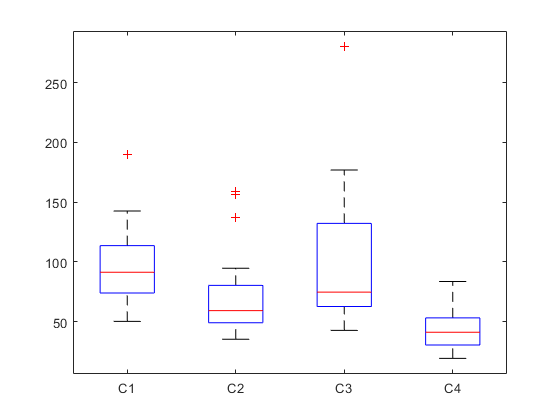


% -- create box plots for each of the tables, solely looking at conditions 1-4
% -- all at the same time
time_bp = boxplot(table2array(t_time(:,1:4)), 'labels', {'C1','C2','C3','C4'});

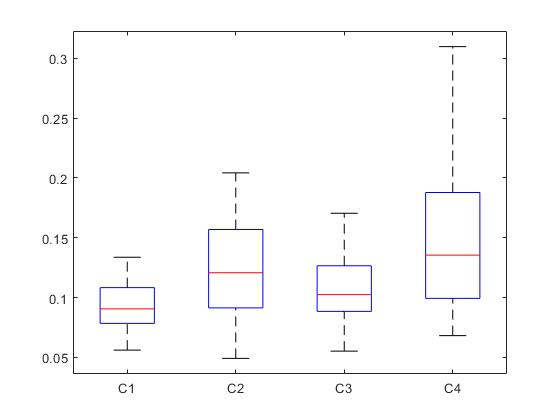

Vel_bp = boxplot(table2array(t_Vel(:,1:4)), 'labels', {'C1','C2','C3','C4'});

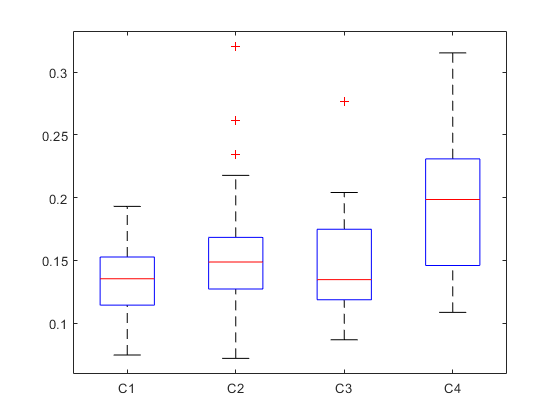

EKFVel_bp = boxplot(table2array(t_EKFVel(:,1:4)), 'labels', {'C1','C2','C3','C4'});

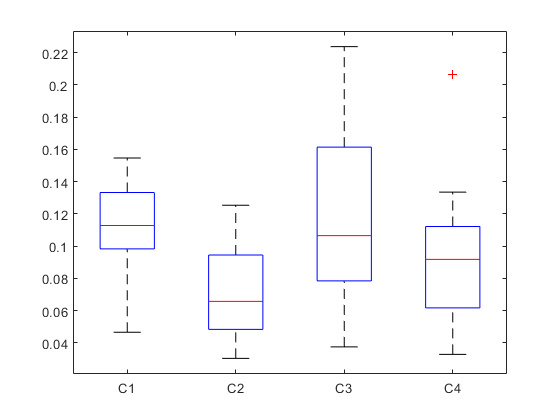

Omega_bp = boxplot(table2array(t_Omega(:,1:4)), 'labels', {'C1','C2','C3','C4'});

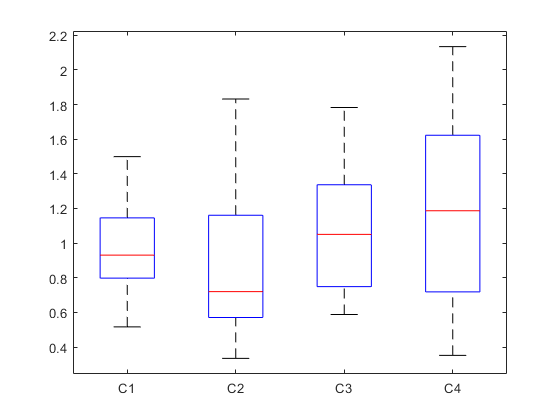

EKFOmega_bp = boxplot(table2array(t_EKFOmega(:,1:4)), 'labels', {'C1','C2','C3','C4'});


% -- define the measurements within the subjects (will  be used for all, for right now)
within=array2table([1 2 3 4]', 'variablenames', {'cond'});

% -- apply the within to the data to get the rm
% -- for right now solely look at conditions 1-4 without the questions
rm_time=fitrm(t_time,'C1-C4~1', 'WithinDesign', within);
rm_Vel=fitrm(t_Vel,'C1-C4~1', 'WithinDesign', within);
rm_EKFVel=fitrm(t_EKFVel,'C1-C4~1', 'WithinDesign', within);
rm_Omega=fitrm(t_Omega,'C1-C4~1', 'WithinDesign', within);
rm_EKFOmega=fitrm(t_EKFOmega,'C1-C4~1', 'WithinDesign', within);

% -- display the repeated measures for all data
rm_time

rm_time =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [24×9 table]
         ResponseNames: {'C1'  'C2'  'C3'  'C4'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [4×1 table]
     WithinFactorNames: {'cond'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×4 table]
            Covariance: [4×4 table]


rm_Vel

rm_Vel =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [24×9 table]
         ResponseNames: {'C1'  'C2'  'C3'  'C4'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [4×1 table]
     WithinFactorNames: {'cond'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×4 table]
            Covariance: [4×4 table]


rm_EKFVel

rm_EKFVel =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [24×9 table]
         ResponseNames: {'C1'  'C2'  'C3'  'C4'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [4×1 table]
     WithinFactorNames: {'cond'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×4 table]
            Covariance: [4×4 table]


rm_Omega

rm_Omega =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [24×9 table]
         ResponseNames: {'C1'  'C2'  'C3'  'C4'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [4×1 table]
     WithinFactorNames: {'cond'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×4 table]
            Covariance: [4×4 table]


rm_EKFOmega

rm_EKFOmega =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [24×9 table]
         ResponseNames: {'C1'  'C2'  'C3'  'C4'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [4×1 table]
     WithinFactorNames: {'cond'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×4 table]
            Covariance: [4×4 table]



% -- after running the fit rm function, run the stats function and display it
stats_time = ranova(rm_time)

stats_time = 2×8 table
                        SumSq    DF    MeanSq      F         pValue      pValueGG      pValueHF     pValueLB 
                        _____    __    ______    ______    __________    _________    __________    _________

    (Intercept):cond    47697     3     15899    14.022    3.1085e-07    8.818e-06    3.4188e-06    0.0010583
    Error(cond)         78235    69    1133.8                                                                


stats_Vel = ranova(rm_Vel)

stats_Vel = 2×8 table
                         SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        ________    __    _________    ______    __________    __________    __________    _________

    (Intercept):cond    0.043499     3       0.0145    11.547    3.1938e-06    8.9677e-05    4.8125e-05    0.0024701
    Error(cond)         0.086645    69    0.0012557                                                                 


stats_EKFVel = ranova(rm_EKFVel)

stats_EKFVel = 2×8 table
                         SumSq      DF     MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        ________    __    _________    ______    __________    __________    __________    _________

    (Intercept):cond    0.060588     3     0.020196    12.472    1.3135e-06    3.3936e-06    1.3135e-06    0.0017851
    Error(cond)          0.11173    69    0.0016193                                                                 


stats_Omega = ranova(rm_Omega)

stats_Omega = 2×8 table
                         SumSq      DF      MeanSq        F         pValue       pValueGG      pValueHF     pValueLB 
                        ________    __    __________    ______    __________    __________    __________    _________

    (Intercept):cond    0.029582     3     0.0098608    11.462    3.4691e-06    2.0171e-05    7.1614e-06    0.0025462
    Error(cond)         0.059362    69    0.00086031                                                                 


stats_EKFOmega = ranova(rm_EKFOmega)

stats_EKFOmega = 2×8 table
                        SumSq     DF    MeanSq       F        pValue     pValueGG    pValueHF    pValueLB
                        ______    __    _______    ______    ________    ________    ________    ________

    (Intercept):cond     1.176     3    0.39201    2.4651    0.069536    0.085675    0.078066    0.13006 
    Error(cond)         10.973    69    0.15903                                                          



% -- check if the stats p value is below 0.05, if it is, display the
% -- pairwise comparisons
if stats_time.pValue(1) < 0.05
    res_time=multcompare(rm_time, 'cond', 'ComparisonType','bonferroni')
end

res_time = 12×7 table
    cond_1    cond_2    Difference    StdErr      pValue       Lower      Upper 
    ______    ______    __________    ______    __________    _______    _______

      1         2         25.873      7.5925      0.014476     3.9595     47.787
      1         3        -1.5769      11.759             1    -35.517     32.363
      1         4         53.002      7.7561    3.4359e-06     30.616     75.388
      2         1        -25.873      7.5925      0.014476    -47.787    -3.9595
      2         3         -27.45      11.796       0.17473    -61.496     6.5956
      2         4         27.129       6.607     0.0025929     8.0592     46.198
      3         1         1.5769      11.759             1    -32.363     35.517
      3   

if stats_Vel.pValue(1) < 0.05
    res_Vel=multcompare(rm_Vel, 'cond', 'ComparisonType','bonferroni')
end

res_Vel = 12×7 table
    cond_1    cond_2    Difference     StdErr       pValue        Lower         Upper   
    ______    ______    __________    _________    _________    __________    __________

      1         2        -0.03029     0.0075266    0.0031763     -0.052014    -0.0085667
      1         3       -0.012436     0.0060505      0.30817       -0.0299     0.0050269
      1         4        -0.05665      0.012784    0.0011526     -0.093548     -0.019752
      2         1         0.03029     0.0075266    0.0031763     0.0085667      0.052014
      2         3        0.017854     0.0082034      0.24027    -0.0058232      0.041531
      2         4        -0.02636      0.012603      0.28629     -0.062735      0.010016
      3         1        0.0

if stats_EKFVel.pValue(1) < 0.05
    res_EKFVel=multcompare(rm_EKFVel, 'cond', 'ComparisonType','bonferroni')
end

res_EKFVel = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue        Lower         Upper   
    ______    ______    __________    _________    __________    __________    __________

      1         2       -0.023475     0.0095614        0.1324     -0.051071     0.0041222
      1         3       -0.013293       0.01075             1     -0.044321      0.017735
      1         4       -0.066996      0.011101    2.2365e-05     -0.099035     -0.034957
      2         1        0.023475     0.0095614        0.1324    -0.0041222      0.051071
      2         3        0.010182      0.013065             1     -0.027528      0.047891
      2         4       -0.043521      0.012696      0.013788     -0.080166    -0.0068761
      3         1

if stats_Omega.pValue(1) < 0.05
    res_Omega=multcompare(rm_Omega, 'cond', 'ComparisonType','bonferroni')
end

res_Omega = 12×7 table
    cond_1    cond_2    Difference     StdErr        pValue         Lower         Upper   
    ______    ______    __________    _________    __________    ___________    __________

      1         2         0.039754    0.0066371    2.4954e-05       0.020597       0.05891
      1         3       -0.0035671    0.0086396             1      -0.028503      0.021369
      1         4          0.02213    0.0077388      0.053191    -0.00020667      0.044466
      2         1        -0.039754    0.0066371    2.4954e-05       -0.05891     -0.020597
      2         3        -0.043321     0.009678     0.0010306      -0.071254     -0.015387
      2         4        -0.017624    0.0071001       0.12476      -0.038117     0.0028689
      3   

if stats_EKFOmega.pValue(1) < 0.05
    res_EKFOmega=multcompare(rm_EKFOmega, 'cond', 'ComparisonType','bonferroni')
end
